# Linear Regression with Interaction Effects

Construct and analyze a linear regression model with interaction effects and interpret the results. 

## Load sample data.

load hospital

To retain only the first column of blood pressure, store data in a table. 

tbl = table(hospital.Sex,hospital.Age,hospital.Weight,hospital.Smoker,hospital.BloodPressure(:,1), ...
    'VariableNames',{'Sex','Age','Weight','Smoker','BloodPressure'});

## Perform stepwise linear regression.

For the initial model, use the full model with all terms and their pairwise interactions. 

mdl = stepwiselm(tbl,'interactions')

The final model in formula form is `BloodPressure ~ 1 + Age + Smoker + Sex*Weight`. This model includes all four main effects (Age, Smoker, Sex, Weight) and the two-way interaction between `Sex` and `Weight`. This model corresponds to 


$$BP = \beta_0 + \beta_A X_A + \beta_{Sm} I_{Sm} + \beta_S I_S + \beta_W
X_W + \beta_{SW} X_WI_S+\epsilon,$$


where 

- $BP$ is the blood pressure 

- $\beta_{i}$ are the coefficients 

- $I_{Sm}$ is the indicator variable for smoking; $I_{Sm} = 1$ indicates a smoking patient whereas $I_{Sm} = 0$ indicates a nonsmoking patient 

- $I_{S}$ is the indicator variable for sex; $I_{S} = 1$ indicates a male patient whereas $I_{S} = 0$ indicates a female patient 

- $X_{A}$ is the `Age` variable 

- $X_{W}$ is the `Weight` variable 

- $\epsilon$ is the error term 

The following table shows the fitted linear model for each gender and smoking combination. 


$$ \begin{array}{|c|c|c|} 
\hline I_{Sm} & I_S & \mbox{Linear Model}\\
\hline 1 \mbox{(Smoker)} & 1 \mbox{(Male)} & \begin{array}{rl} BP &= \left( \beta_0 + \beta_{Sm} + \beta_S \right) + \beta_AX_A + \left(\beta_W + \beta_{SW} \right) X_W\\ \hat{BP} &= 107.5617 + 0.11584X_A + 0.11826X_W \end{array}\\
\hline 1 \mbox{(Smoker)} & 0 \mbox{(Female)} & \begin{array}{rl} BP &= \left( \beta_0 + \beta_{Sm} \right) + \beta_A X_A + \beta_W X_W \\ \hat{BP} &= 143.0007 + 0.11584X_A - 0.1393X_W \end{array}\\
\hline 0 \mbox{(Nonsmoker)} & 1 \mbox{(Male)} & \begin{array}{rl} BP &= \left( \beta_0 + \beta_S \right) + \beta_A X_A + \left( \beta_W + \beta_{SW} \right) X_W\\ \hat{BP} &= 97.901 + 0.11584X_A + 0.11826X_W\end{array}\\
\hline 0 \mbox{(Nonsmoker)} & 0 \mbox{(Female)} & \begin{array}{rl} BP &= \beta_0 + \beta_A X_A + \beta_W X_W \\ \hat{BP} &= 133.17 + 0.11584X_A - 0.1393X_W \end{array}\\
\hline \end{array}$$


As seen from these models, $\beta_{Sm}$ and $\beta_{S}$ show how much the intercept of the response function changes when the indicator variable takes the value 1 compared to when it takes the value 0. $\beta_{SW}$, however, shows the effect of the Weight variable on the response variable when the indicator variable for sex takes the value 1 compared to when it takes the value 0. You can explore the main and interaction effects in the final model using the methods of the `LinearModel` class as follows.

## Plot prediction slice plots.

figure
plotSlice(mdl)

This plot shows the main effects for all predictor variables. The green line in each panel shows the change in the response variable as a function of the predictor variable when all other predictor variables are held constant. For example, for a smoking male patient aged 37.5, the expected blood pressure increases as the weight of the patient increases, given all else the same.

The dashed red curves in each panel show the 95% confidence bounds for the predicted response values.

The horizontal dashed line in each panel shows the predicted response for the specific value of the predictor variable corresponding to the vertical dashed line. You can drag these lines to get the predicted response values at other predictor values, as shown next.

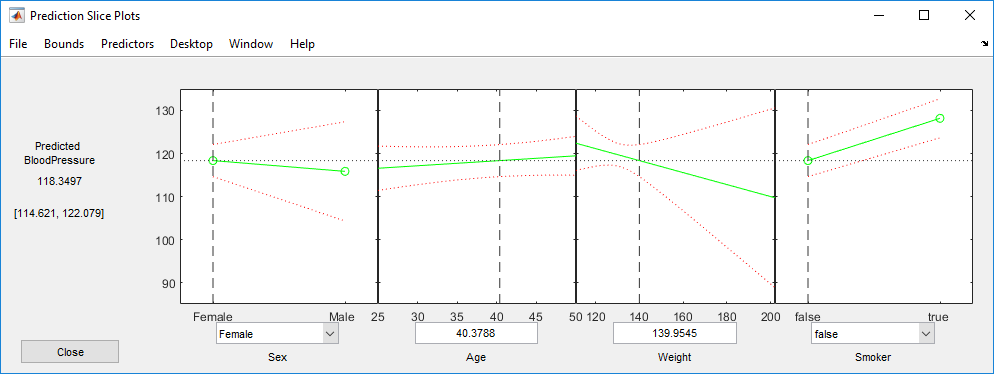

For example, the predicted value of the response variable is 118.3497 when a patient is female, nonsmoking, age 40.3788, and weighs 139.9545 pounds. The values in the square brackets, [114.621, 122.079], show the lower and upper limits of a 95% confidence interval for the estimated response. Note that, for a nonsmoking female patient, the expected blood pressure decreases as the weight increases, given all else is held constant.

## Plot main effects.

plotEffects(mdl)

This plot displays the main effects. The circles show the magnitude of the effect and the blue lines show the upper and lower confidence limits for the main effect. For example, being a smoker increases the expected blood pressure by 10 units, compared to being a nonsmoker, given all else is held constant. Expected blood pressure increases about two units for males compared to females, again, given other predictors held constant. An increase in age from 25 to 50 causes an expected increase of 4 units, whereas a change in weight from 111 to 202 causes about a 4-unit decrease in the expected blood pressure, given all else held constant.

## Plot interaction effects.

figure
plotInteraction(mdl,'Sex','Weight')

This plot displays the impact of a change in one factor given the other factor is fixed at a value. 

Be cautious while interpreting the interaction effects. When there is not enough data on all factor combinations or the data is highly correlated, it might be difficult to determine the interaction effect of changing one factor while keeping the other fixed. In such cases, the estimated interaction effect is an extrapolation from the data.

The blue circles show the main effect of a specific term, as in the main effects plot. The red circles show the impact of a change in one term for fixed values of the other term. For example, in the bottom half of this plot, the red circles show the impact of a weight change in female and male patients, separately. You can see that an increase in a female’s weight from 111 to 202 pounds causes about a 14-unit decrease in the expected blood pressure, while an increase of the same amount in the weight of a male patient causes about a 5-unit increase in the expected blood pressure, again given other predictors are held constant.

## Plot prediction effects.

figure
plotInteraction(mdl,'Sex','Weight','predictions')

This plot shows the effect of changing one variable as the other predictor variable is held constant. In this example, the last figure shows the response variable, blood pressure, as a function of weight, when the variable sex is fixed at males and females. The lines for males and females are crossing which indicates a strong interaction between weight and sex. You can see that the expected blood pressure increases as the weight of a male patient increases, but decreases as the weight of a female patient increases.

*Copyright 2012 The MathWorks, Inc.*